Import 3D occupancy map.

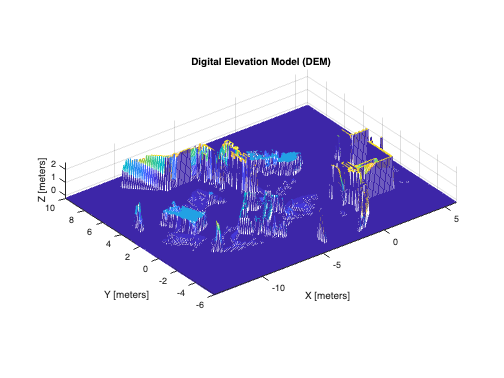

% Import the 3D occupancy map
map3D = importOccupancyMap3D("my_octomap_cons.bt");
show(map3D);

Iterate each point (step size) in the occupancy point and store the occupied points.

% Define the ranges and step size
lower_limit = -0.2;
step_size = 0.1;

x_range = -14:step_size:6;
y_range = -6:step_size:10;
z_range = lower_limit:step_size:6;

% Preallocate arrays
x_len = length(x_range);
y_len = length(y_range);
z_len = length(z_range);

% Initialize the recordedPoints matrix to hold the highest z values for each (x, y) pair
Z = -inf(y_len, x_len);

% Iterate through x, y, z ranges
for i = 1:x_len
    for j = 1:y_len
        for k = 1:z_len
            occupancy = getOccupancy(map3D, [x_range(i), y_range(j), z_range(k)]);
            if occupancy > 0.65 && z_range(k) > Z(j, i)
                Z(j, i) = z_range(k);
            end
        end
    end
end

% Convert recorded points into a Digital Elevation Model (DEM)
[X, Y] = meshgrid(x_range, y_range);

% Replace -inf values with NaN to handle missing data appropriately in the plot
Z(Z < lower_limit) = lower_limit;

Visulization

% Visualize the DEM
figure;
mesh(X, Y, Z);
title('Digital Elevation Model (DEM)');
xlabel('X [meters]');
ylabel('Y [meters]');
zlabel('Z [meters]');
grid on;
axis equal;


% Alternatively, use surf for visualization
figure;
surf(X, Y, Z);
title('Digital Elevation Model (DEM)');
xlabel('X [meters]');
ylabel('Y [meters]');
zlabel('Z [meters]');
grid on;
axis equal;
shading interp; % Optional: makes the surface plot smoother

xlim([-12.0 4.5])
ylim([-6.0 7.2])
zlim([-1.00 1.93])
view([-37.50 30.00])
 
ax = gca;
chart = ax.Children(1);
datatip(chart,-11.8,-5.1,-1);
datatip(chart,-8.26,-2.42,-1);
datatip(chart,-9.72,3.4,0.58);
datatip(chart,-8.26,-2.24,0.08);
datatip(chart,-6.08,-1.34,1.04);
datatip(chart,-6.08,-1.34,1.04);

**Path Planning**

Constuct Z-layer

% Query and store the Z-height
zLayer = mapLayer(flipud(Z),LayerName="Z");

Calculate the gradient and convert to cost

[gx,gy] = gradient(Z);
figure
contour(X,Y,Z)
title("Terrain Slope")
hold on
quiver(X,Y,gx,gy)
axis equal
hold off

Store the gradients

dzdx = mapLayer(flipud(gx),LayerName="dzdx");
dzdy = mapLayer(flipud(gy),LayerName="dzdy");

Define the maximum incline angle and convert it to slope

maxinclineangle = 15; % Degrees
maxSlope = tand(maxinclineangle); % Max preferred slope for vehicle

Visualize the unweighted slope-to-cost function.

slope2cost = @(x)exampleHelperGradientToCost(maxSlope,flipud(x));
slope = linspace(-2*maxSlope,2*maxSlope,100);
plot(slope,slope2cost(slope))
hold on
xline(maxSlope*[-1 1],"r:")
yline(1,"b:")
title("Cost vs Slope")
xlabel("Slope")
ylabel("Cost")
axis square

Calculate costs using the slope function, and store them in map layers.

xCost = mapLayer(slope2cost(gx),LayerName="xCost");
yCost = mapLayer(slope2cost(gy),LayerName="yCost");
diagCost = mapLayer(slope2cost(sqrt(gx.^2+gy.^2)),LayerName="diagCost");

**Terrain Obstacles**

% Set RNG seed for repeatable results
rng(4)

% Assuming X is defined elsewhere in your code
% Replace the following line with the actual dimensions of X or its size
% X = <your matrix here>;

% Create obstacle probabilities
obstacleprob = zeros(y_len, x_len);

% Create the binary occupancy map for obstacles
obstacleMap = binaryOccupancyMap(flipud(obstacleprob > 0.998), LayerName="obstacles");

% Create the terrain obstacles map without including obstacleMap
terrainObstacles = binaryOccupancyMap(zeros(size(obstacleprob)), LayerName="terrainObstacles");

% Inflate the terrain obstacles map
inflate(terrainObstacles, 2);

% Extract map data
obstaclesAndTerrain = double(getMapData(terrainObstacles));

% Slope constraints checking (assuming xCost, yCost, diagCost are defined)
% mInvalidSlope = <your slope constraints logic here>;

% Calculate cells that violate all three slope constraints
mInvalidSlope = xCost > 0.1 & yCost > 0.1 & diagCost > 0.1;

% Block off cells that violate all three slope constraints in the terrain map
obstaclesAndTerrain(mInvalidSlope) = true;

% % Ensure the original obstacles are not included in the terrain map
% originalObstacles = getMapData(obstacleMap);
% obstaclesAndTerrain(originalObstacles) = false;

% Update the terrainObstacles map with the new data
setMapData(terrainObstacles, obstaclesAndTerrain);

% Display the maps
figure
show(obstacleMap,Parent=subplot(1,2,1))
show(terrainObstacles,Parent=subplot(1,2,2))
title("Obstacles and Gradient-Restricted Regions")

**Combine Individual Map Layers**

costMap = multiLayerMap({zLayer dzdx dzdy terrainObstacles xCost yCost diagCost});
xCost.GridOriginInLocal = -xCost.GridSize/xCost.Resolution/2

xCost =   mapLayer with properties:

   mapLayer Properties
               DataSize: [161 201]
               DataType: 'double'
           DefaultValue: 0
               GridSize: [161 201]
              LayerName: 'xCost'
    GridLocationInWorld: [-80.500000000000000 -1.005000000000000e+02]
      GridOriginInLocal: [-80.500000000000000 -1.005000000000000e+02]
     LocalOriginInWorld: [0 0]
             Resolution: 1
           XLocalLimits: [-80.500000000000000 1.205000000000000e+02]
           YLocalLimits: [-1.005000000000000e+02 60.500000000000000]
           XWorldLimits: [-80.500000000000000 1.205000000000000e+02]
           YWorldLimits: [-1.005000000000000e+02 60.500000000000000]
        GetTransformFcn: []
        SetTransformFcn: []


Visualise

% Restore map to original settings
costMap.GridOriginInLocal = [0 0];

figure(5)
obstaclesAndTerrain(obstaclesAndTerrain < 1) = nan; % Turn 0s to NaNs for plotting on costmaps

% Add helper folders to path
addpath("Analysis");
show(visualizationHelper,xCost,subplot(1,3,1),hold="on",title="X Slope",Threshold=1);
surface(flipud(obstaclesAndTerrain),FaceColor=[0 0 0])
show(visualizationHelper,yCost,subplot(1,3,2),hold="on",title="Y Slope",Threshold=1);
surface(flipud(obstaclesAndTerrain),FaceColor=[0 0 0])

show(visualizationHelper,diagCost,subplot(1,3,3),hold="on",title="Diagonal Slope",Threshold=1);
surface(flipud(obstaclesAndTerrain),FaceColor=[0 0 0])
sgtitle("Unweighted Costs with Obstacles")

**Plan Paths Using 2.5-D Heuristics**

plannerType = "plannerAStarGrid";
start = [54 131 pi/3];
goal  = [143 104 pi/3];

% If the planner type is plannerAStarGrid, convert the start and goal locations to grid coordinates.
if strcmp(plannerType,"plannerAStarGrid")
    start = world2grid(costMap,start(:,1:2));
    goal  = world2grid(costMap,goal(:,1:2));
end

gWeight = 1;
hWeight = 1;
[defaultPlanner,heightAwarePlanner,gradientAwarePlanner,rolloverAwarePlanner] = exampleHelperCreatePlannerObject(plannerType,costMap,gWeight,hWeight);

% Planners return a sequence of IJ cells
paths = cell(4,1);
pathNames = ["Default","Elevation-Aware Path","Gradient-Aware Path","Rollover-Aware Path"];
planningTime = nan(4,1);
tic;
paths{1} = plan(defaultPlanner,start,goal);
planningTime(1) = toc;
paths{2} = plan(heightAwarePlanner,start,goal);
planningTime(2) = toc-planningTime(1);
paths{3} = plan(gradientAwarePlanner,start,goal);
planningTime(3) = toc-planningTime(2);
paths{4} = plan(rolloverAwarePlanner,start,goal);
planningTime(4) = toc-planningTime(3);

if strcmp(plannerType,"plannerHybridAStar")
    for i=1:4
        paths{i} = paths{i}.States;
    end
end